# Considerações a respeito de Kalman -- caso não polinomial

No capítulo 5 do livro do Zarchan ele aborda o caso em que o sinal do sistema amostrado (com ruído branco) não apresenta necessariamente ordem polinomial. Para este capítulo em específico, ele aborda o caso de se tentar estimar um sinal senoidal com ruído. São abordadas algumas técnicas envolvidas.

## Tentativa de rastreio do sistema senoidal por sistema de 2º ordem.

Nesse caso, não haveria nenhum tipo de entrada (ou seja, a matriz **B **é nula). Sendo assim, o modelo para estimação do Filtro de Kalman, agora simplificado, é dado por:


$$\hat{x}_{k} = \Phi_k \hat{x}_{k-1} + K_{k}[y_{k} - H\Phi_{k}\hat{x}_{k-1}]$$


Nesse contexto, utilizando as diretrizes para uma função senoidal tem-se que:


$$\begin{array}{l}
x\left(t\right)=A\text{ }\mathrm{sen}\left(\omega \text{ }t\right)\\
\dot{x} \left(t\right)=A\omega \text{ }\mathrm{cos}\left(\omega \text{ }t\right)\\
\ddot{\text{ }x} \left(t\right)=-A\omega {\text{ }}^2 \text{ }\mathrm{sen}\left(\omega \text{ }t\right)
\end{array}$$


em que **A **é a amplitude do sinal e $\omega$ é a frequência do sinal. Olhando as equações no espaço de estados, tem-se que:


$$\left\lbrack \begin{array}{c}
\dot{\text{ }x} \\
\ddot{\text{ }x} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 1\\
-\omega {\text{ }}^2  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
\dot{\text{ }x} 
\end{array}\right\rbrack$$


Importante destacar que essa premissa que estamos trazendo diz respeito ao sinal em que já sabemos que é senoidal e que está cheio de ruído. 

Inicialmente eu apresentarei o meu sistema no espaço de estados a tempo contínuo (a física por trás dele).

clear all; close all; clc;
syms OMEGA s

% Matrizes de estado do meu sistema.
A = [    0    1;
     -OMEGA^2 0];
B = [0;
     0];
C = [1 0];       % Faço a medição apenas nesse sinal.


Vamos resolver o problema da dinâmica do meu sistema em tempo contínuo.

I = eye(2);      % Identidade do meu sistema.

phi_t = ilaplace(inv(s*I - A))

$$phi\_t = \left(\begin{array}{cc} \cos\left(\mathrm{OMEGA}\,t\right) & \frac{\sin\left(\mathrm{OMEGA}\,t\right)}{\mathrm{OMEGA}}\\ -\mathrm{OMEGA}\,\sin\left(\mathrm{OMEGA}\,t\right) & \cos\left(\mathrm{OMEGA}\,t\right) \end{array}\right)$$

No caso abordado para este problema, temos de criar um sinal senoidal que será amostrado a cada 0,1s e tem duração total de 20s. Sendo assim, seja o sinal senoidal:

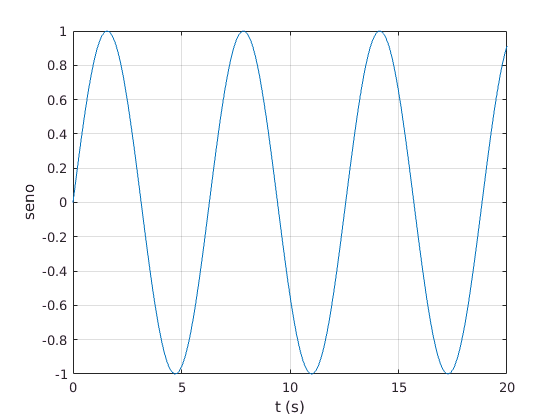

% Tempo de amostragem e tempo total do 'ensaio'.
Ts    = 0.1;        
t     = linspace(0, 20, (20-0)/Ts + 1);

% Sinal sem ruído
omega = 1;           % Frequência do sinal.
Amp   = 1;           % Amplitude do sinal.
seno  = Amp*sin(omega*t);

% Apenas para plot intermediário.
plot(t, seno); grid;
xlabel('t (s)');
ylabel('seno');

Como eu já determinei a matriz **A** do sistema, eu agora realizarei a discretização do sistema (no caso apenas a matriz **A**, para utilizar a frequência de amostragem do sistema).

% Determinação da matriz discretizada -- Fazer por variável simbólica dá uma treta ferrada.
phi_k = [cos(omega*Ts) sin(omega*Ts)/omega;
         -omega*sin(omega*Ts)  cos(omega*Ts)];

Até aqui tudo bem. A ideia agora é criar um sinal senoidal com ruído (sobre o qual será passado o Filtro de Kalman).

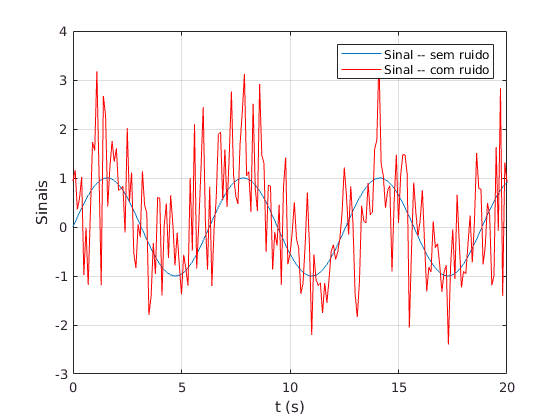

% Colocar ruído com média zero e desvio padrão 1 -- assumido para este exemplo.
desvio_padrao = 1;                                 
ruido = 0 + desvio_padrao*randn(max(size(seno)), 1);    
ruido = ruido';  

% Sinal senoidal, o qual desejamos filtrar, com ruído.
seno_ruidoso = seno + ruido;

% Fazer comparação entre o sinal perfeito e o ruidoso.
plot(t, seno, t, seno_ruidoso, 'r'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal -- com ruido');

Vamos utilizar então as técnicas para a filtragem desse sinal.

## 1º caso -- modelo é assumido perfeito ao sinal o qual desejamos medir.

Esse caso é interessante, pois nunca acontecerá na vida real. Serve apenas para fins educativos. Como sabemos que o sinal é "perfeito" não adicionameremos nenhum tipo de incerteza de modelo e vejamos como que o sistema se comporta.

Vamos agora determinar a matriz Q a tempo discreto. Importante saber quem é a mesma, em tempo contínuo é dada por:


$$Q=E\left\lbrack {\mathrm{ww}}^T \right\rbrack$$


Como não há erro de processo envolvido no sistema (ou seja, é considerada essa situação), a nossa matriz $Q$ será nula e quadrada de ordem 2. Quando a gente coloca essa matriz para determinação da matriz $Q_k$ dará no final uma matriz nula, quadrada e de ordem 2 (só verificar nas equações). Isso pode ser comprovado substituindo Q nula na equação abaixo:


$$Q_k = \int_{0}^{T_s}\Phi(\tau)\textbf{Q}\Phi^{T}(\tau) d\tau$$


% Não foi assumido erro entre o sistema e o sinal medido.
Q   = zeros(2,2);

% 2) Podemos também fazer no 'brute force', Para tal, tem-se que:
% PRODUTO = phi_t * Q * (phi_t');
% Q_k     = int(PRODUTO, [0 Ts]);
Q_k = Q;

% Ruído da medida (apenas uma única medida do sistema).
R_k = desvio_padrao^2;

Inicialização do sistema para a Filtragem de Kalman

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(2);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0];
y        = seno_ruidoso;

Executo a recursão do Filtro de Kalman.

% Recursão de Kalman.
for k = 2:max(size(seno))
    
    % Equação de Riccati.
    M{k} = (phi_k) * P{k-1} * (phi_k') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k*x_hat{k-1} + K{k}*(y(k) - C*phi_k*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
for i = 1:max(size(y))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
end

Vamos plotar o resultado do sistema e verificar o comportamento do filtro.

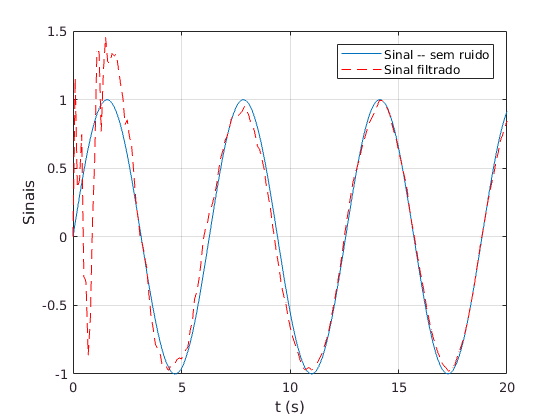

plot(t, seno, t, x_end, 'r--'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal filtrado');

Percebe-se que o sistema em princípio deu uma certa seguida no sinal o qual eu desejava verificar o comportamento. A parte inicial é meio zoada pois não sabemos "nada" a respeito do nosso sistema e com isso a gente inicializou as matrizes de covariâncias absurdamente altas. Deve-se notar no entanto que foi assumido casamento perfeito do meu sistema com sinal verificado. Algumas situações serão exploradas no decorrer desse programa e é importante que a gente consiga entender o que ocorre em diversas situações.

## 2º caso -- a matriz da dinâmica fundamental é truncada.

Esse caso aborda a situação em que a invés de determinarmos a matriz $\Phi \text{ }\left(t\right)$ exata (no caso I), a gente truncará ela e utilizará apenas os dois primeiros termos da matriz do sistema.

Nesse caso, a matriz truncada entrará tanto na dinâmica do Filtro quanto nas equações de Riccati.

% Vamos separar em termos da somatória de matrizes.
termo1 = eye(2);
termo2 = Ts*[    0     1;
             -omega^2  0];
phi_k_s = termo1 + termo2;    % dinâmica simplificada.


Vamos verificar o resultado com o sistema simplificado.

clear x_hat P M K x_end xd_end

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(2);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0];
y        = seno_ruidoso;

% Recursão de Kalman.
for k = 2:max(size(seno))
    
    % Equação de Riccati.
    M{k} = (phi_k_s) * P{k-1} * (phi_k_s') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k_s*x_hat{k-1} + K{k}*(y(k) - C*phi_k_s*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
for i = 1:max(size(y))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
end

Vamos plotar o resultado do sistema e verificar o comportamento do filtro.

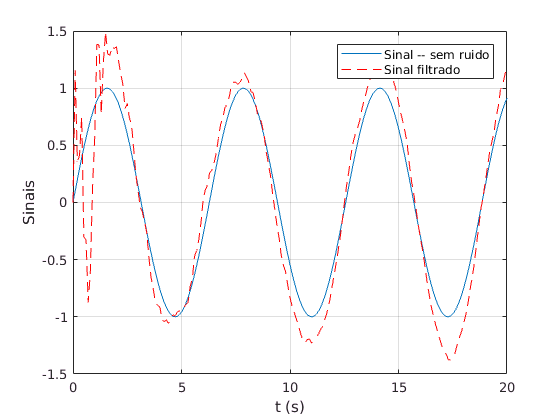

plot(t, seno, t, x_end, 'r--'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal filtrado');

Percebe-se que apesar de a estimativa ainda "seguir" o sinal senoidal, o resultado do primeiro caso foi bem melhor (afinal a gente utilizou o sistema "perfeito", ao invés de um simplificado).

## 3º caso -- matriz perfeita na dinâmica e assumir dinâmica da matriz de Riccati simplificada.

Agora a dinâmica completa "perfeita" (vide caso 1):

% Dinâmica perfeita do meu sistema.
phi_k = [     cos(omega*Ts)    sin(omega*Ts)/omega;
         -omega*sin(omega*Ts)  cos(omega*Ts)];

Vamos rodar uma simulação:

clear x_hat P M K x_end xd_end

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(2);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0];
y        = seno_ruidoso;
         
% Recursão de Kalman.
for k = 2:max(size(seno))
    
    % Equação de Riccati.
    M{k} = (phi_k_s) * P{k-1} * (phi_k_s') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k*x_hat{k-1} + K{k}*(y(k) - C*phi_k*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
for i = 1:max(size(y))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
end

Vamos plotar o resultado do sistema e verificar o comportamento do filtro.

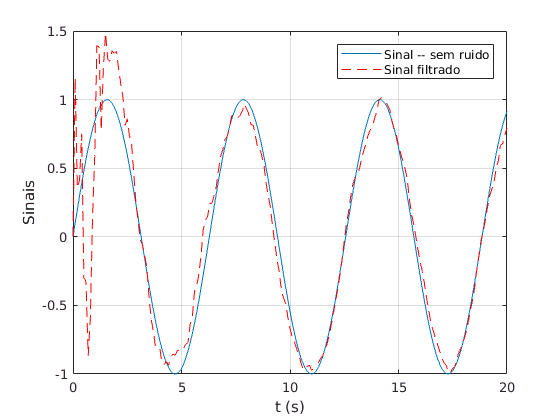

plot(t, seno, t, x_end, 'r--'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal filtrado');

Segundo o livro do Zarchan, o sistema deve ter uma dinâmica muito parecida com aquela dinâmica do caso 1. E de fato a gente percebe, visualmente que existe sim uma certa proximidade entre o caso 1 e o caso 2 da dinãmica do sistema. Observar que ele coloca uma premissa importante: a dinâmica do sistema é mais importante do que os ganhos do Filtro. 

## 4º caso -- assumir dinâmica perfeita mas com frequência errada em 100%.

Esse caso é interessante, pois apesar de o nosso sinal ruidoso estar com uma frequência de 1rad/s, a matriz representativa da dinâmica do sistema estará com um erro de 100% (no caso, 2 ao invés de 1). Sendo assim, façamos a simulação para esse caso.

Agora a dinâmica completa "perfeita" (vide caso 1):

% Dinâmica perfeita do meu sistema com erro de 100% na entrada do sinal.
omega = 2*omega;

phi_k = [     cos(omega*Ts)    sin(omega*Ts)/omega;
         -omega*sin(omega*Ts)  cos(omega*Ts)];

Vamos rodar uma simulação:

clear x_hat P M K x_end xd_end

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(2);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0];
y        = seno_ruidoso;
         
% Recursão de Kalman.
for k = 2:max(size(seno))
    
    % Equação de Riccati.
    M{k} = (phi_k) * P{k-1} * (phi_k') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k*x_hat{k-1} + K{k}*(y(k) - C*phi_k*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
for i = 1:max(size(y))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
end

Vamos plotar o resultado do sistema e verificar o comportamento do filtro.

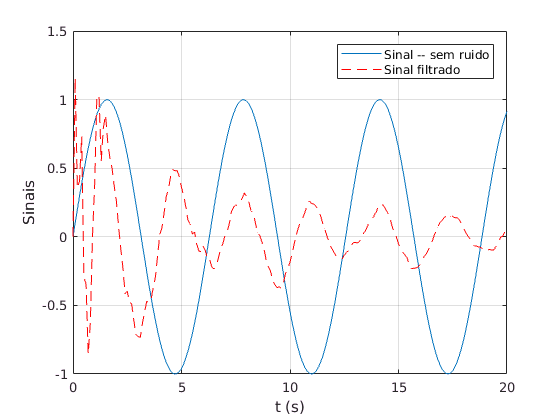

plot(t, seno, t, x_end, 'r--'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal filtrado');

Esse caso mostra claramente a dependencia do Filtro de Kalman ao erro de modelagem. 

Alguém poderia simplesmente pensar numa solução para este problem: inserir um erro de modelagem (matriz **Q**, onde a gente ponderaria a nossa incerteza nessa matriz).

Nesse caso, vamo tentar incorporar um erro de modelagem para esse caso em específico. Deixo a minha matriz $\Phi \left(t\right)$errada de propósito em 100% no modelo.

omega = 2;
syms t
phi_t = [        cos(omega*t), sin(omega*t)/omega;
          -omega*sin(omega*t),       cos(omega*t)]

$$phi\_t = \left(\begin{array}{cc} \cos\left(2\,t\right) & \frac{\sin\left(2\,t\right)}{2}\\ -2\,\sin\left(2\,t\right) & \cos\left(2\,t\right) \end{array}\right)$$

Faço o ajuste na matriz **Q **para a inclusão das possíveis incertezas do sistema modelado.

% Erro inicialmente assumido.
Q2 = 0.1*eye(2);

% Fazer o cálculo de maneira bruta.
PRODUTO = phi_t * Q2 * (phi_t');
Q_k     = int(PRODUTO, [0 Ts]);

% Converte para numérico para ser utilizado nas equações do Filtro de Kalman.
Q_k     = double(Q_k);

Agora a dinâmica completa "perfeita" (com 100% de erro no modelo em estudo):

% Dinâmica perfeita do meu sistema com erro de 100% na entrada do sinal.
omega = 2*omega;

phi_k = [     cos(omega*Ts)    sin(omega*Ts)/omega;
         -omega*sin(omega*Ts)  cos(omega*Ts)];

Vamos rodar uma simulação:

clear x_hat P M K x_end xd_end

% Inicialização do sistema de Kalman.
P{1}  = 999999999*eye(2);

% Estimativas iniciais dos estados do sistema.
x_hat{1} = [0; 0];
y        = seno_ruidoso;
         
% Recursão de Kalman.
for k = 2:max(size(seno))
    
    % Equação de Riccati.
    M{k} = (phi_k) * P{k-1} * (phi_k') + Q_k;
    K{k} = M{k} * (C') * inv(C * M{k} * (C') + R_k);
    P{k} = (I - K{k}*C)*M{k};
    
    % Atualização dos estados.
    x_hat{k} = phi_k*x_hat{k-1} + K{k}*(y(k) - C*phi_k*x_hat{k-1});
end

% Separa os resultados para facilitar o plot.
t = linspace(0, 20, (20-0)/Ts + 1);
for i = 1:max(size(y))
   x_end(i)   = x_hat{i}(1,1); 
   xd_end(i)  = x_hat{i}(2,1);
end

Vamos plotar o resultado do sistema e verificar o comportamento do filtro.

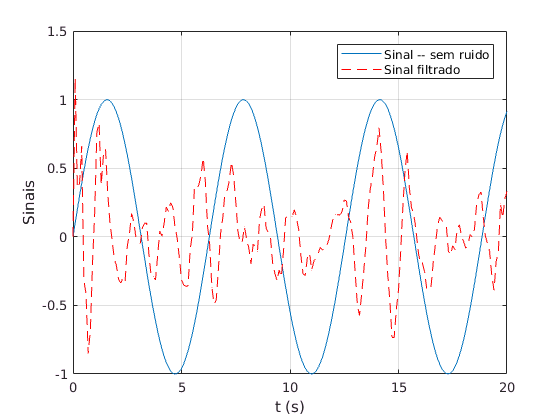

plot(t, seno, t, x_end, 'r--'); grid;
xlabel('t (s)');
ylabel('Sinais');
legend('Sinal -- sem ruido', 'Sinal filtrado');

Percebe-se nesse caso que mesmo com a incidência de erro no modelo matemático do meu sistema, o que a gente tem é um sinal que em tese não consegue ser determinado (mesmo se utilizando do artifício de se considerar possíveis erros na modelagem do sistema). Retornaremos a esse problema lá no futuro (possivelmente no capítulo 10).